# Pytorch CSI Feedback with Autoencoders

clc
clear
close all

## **Parameters Setting**

envir = 'indoor'; %'indoor' or 'outdoor'
% image params
img_height = 32;
img_width = 32;
img_channels = 2;
img_total = img_height*img_width*img_channels;
% network params
residual_num = 2;
encoded_dim = 512;  %compress rate=1/4->dim.=512, compress rate=1/16->dim.=128, compress rate=1/32->dim.=64, compress rate=1/64->dim.=32

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

% autoencoderLGraph = layerGraph([ ...
%     % Encoder
%     imageInputLayer([img_height,img_width,img_channels],"Name","Htrunc", ...
%       "Normalization","none","Name","Enc_Input")
% 
%     convolution2dLayer([3 3],2,"Padding","same","Name","Enc_Conv")
%     batchNormalizationLayer("Epsilon",0.001,"MeanDecay",0.99, ...
%       "VarianceDecay",0.99,"Name","Enc_BN")
%     leakyReluLayer(0.3,"Name","Enc_leakyRelu")
% 
%     flattenLayer("Name","Enc_flatten")
% 
%     fullyConnectedLayer(encoded_dim,"Name","Enc_FC")
% 
%     sigmoidLayer("Name","Enc_Sigmoid")
% 
%     % Decoder
%     fullyConnectedLayer(img_total,"Name","Dec_FC")
% 
%     functionLayer(@(x)dlarray(reshape(x,img_height,img_width,img_channels,[]),'SSCB'), ...
%       "Formattable",true,"Acceleratable",true,"Name","Dec_Reshape")
%     ]);
% 
% autoencoderLGraph = ...
%   helperCSINetAddResidualLayers(autoencoderLGraph, "Dec_Reshape");
% 
% autoencoderLGraph = addLayers(autoencoderLGraph, ...
%     [convolution2dLayer([3 3],2,"Padding","same","Name","Dec_Conv") ...
%     sigmoidLayer("Name","Dec_Sigmoid") ...
%     regressionLayer("Name","Dec_Output")]);
% autoencoderLGraph = ...
%   connectLayers(autoencoderLGraph,"leakyRelu_2_3","Dec_Conv");

## Load Network

model_name = "model_CsiNet_"+envir+"_dim"+num2str(encoded_dim);
load("Sigmoid model/"+model_name+".mat")
load("Matlab sigmoid model/csiTrainedNetwork_"+num2str(encoded_dim)+".mat") %% load DAGNetwork

net= layerGraph(net);

% Enc_Conv
Enc_Conv_Weight_temp = single(zeros(size(net.Layers(2,1).Weights)));
for filter=1:size(net.Layers(2,1).Weights,4)
    Enc_Conv_Weight_temp(:,:,1,filter) = reshape(Enc_Conv_Weight(filter,1,:,:),3,3).';
    Enc_Conv_Weight_temp(:,:,2,filter) = reshape(Enc_Conv_Weight(filter,2,:,:),3,3).';
end
layer = setfield(net.Layers(2,1),'Weights',Enc_Conv_Weight_temp);
net = replaceLayer(net,'Enc_Conv',layer);

Enc_Conv_Bias_temp = single(zeros(size(net.Layers(2,1).Bias)));
for index=1:size(net.Layers(2,1).Bias,3)
    Enc_Conv_Bias_temp(:,:,index) = Enc_Conv_Bias(index);
end
layer = setfield(net.Layers(2,1),'Bias',Enc_Conv_Bias_temp);
net = replaceLayer(net,'Enc_Conv',layer);

% Enc_BN
Enc_BN_Weight_temp = single(zeros(size(net.Layers(3,1).Scale)));
Enc_BN_Bias_temp = single(zeros(size(net.Layers(3,1).Offset)));
Enc_BN_Mean_temp = single(zeros(size(net.Layers(3,1).TrainedMean)));
Enc_BN_Var_temp = single(zeros(size(net.Layers(3,1).TrainedVariance)));
for index=1:size(net.Layers(3,1).Scale,3)
    Enc_BN_Weight_temp(:,:,index) = Enc_BN_Weight(index);
    Enc_BN_Bias_temp(:,:,index) = Enc_BN_Bias(index);
    Enc_BN_Mean_temp(:,:,index) = Enc_BN_Mean(index);
    Enc_BN_Var_temp(:,:,index) = Enc_BN_Var(index);
end
layer = setfield(net.Layers(3,1),'Scale',Enc_BN_Weight_temp);
net = replaceLayer(net,'Enc_BN',layer);
layer = setfield(net.Layers(3,1),'Offset',Enc_BN_Bias_temp);
net = replaceLayer(net,'Enc_BN',layer);
layer = setfield(net.Layers(3,1),'TrainedMean',Enc_BN_Mean_temp);
net = replaceLayer(net,'Enc_BN',layer);
layer = setfield(net.Layers(3,1),'TrainedVariance',Enc_BN_Var_temp);
net = replaceLayer(net,'Enc_BN',layer);

% Enc_FC
layer = setfield(net.Layers(6,1),'Weights',Enc_FC_Weight);
net = replaceLayer(net,'Enc_FC',layer);
layer = setfield(net.Layers(6,1),'Bias',Enc_FC_Bias.');
net = replaceLayer(net,'Enc_FC',layer);

% Dec_FC
layer = setfield(net.Layers(8,1),'Weights',Dec_FC_Weight);
net = replaceLayer(net,'Dec_FC',layer);
layer = setfield(net.Layers(8,1),'Bias',Dec_FC_Bias.');
net = replaceLayer(net,'Dec_FC',layer);

% Res_Conv_i_1
Res_1_1_Weight_Conv_temp = single(zeros(size(net.Layers(10,1).Weights)));
Res_2_1_Weight_Conv_temp = single(zeros(size(net.Layers(20,1).Weights)));
for filter=1:size(net.Layers(10,1).Weights,4)
    Res_1_1_Weight_Conv_temp(:,:,1,filter) = reshape(Res_Conv_1_1_Weight(filter,1,:,:),3,3).';
    Res_1_1_Weight_Conv_temp(:,:,2,filter) = reshape(Res_Conv_1_1_Weight(filter,2,:,:),3,3).';
    Res_2_1_Weight_Conv_temp(:,:,1,filter) = reshape(Res_Conv_2_1_Weight(filter,1,:,:),3,3).';
    Res_2_1_Weight_Conv_temp(:,:,2,filter) = reshape(Res_Conv_2_1_Weight(filter,2,:,:),3,3).';
end
layer = setfield(net.Layers(10,1),'Weights',Res_1_1_Weight_Conv_temp);
net = replaceLayer(net,'Res_Conv_1_1',layer);
layer = setfield(net.Layers(20,1),'Weights',Res_2_1_Weight_Conv_temp);
net = replaceLayer(net,'Res_Conv_2_1',layer);

Res_1_1_Bias_Conv_temp = single(zeros(size(net.Layers(10,1).Bias)));
Res_2_1_Bias_Conv_temp = single(zeros(size(net.Layers(20,1).Bias)));
for index=1:size(net.Layers(10,1).Bias,3)
    Res_1_1_Bias_Conv_temp(:,:,index) = Res_Conv_1_1_Bias(index);
    Res_2_1_Bias_Conv_temp(:,:,index) = Res_Conv_2_1_Bias(index);
end
layer = setfield(net.Layers(10,1),'Bias',Res_1_1_Bias_Conv_temp);
net = replaceLayer(net,'Res_Conv_1_1',layer);
layer = setfield(net.Layers(20,1),'Bias',Res_2_1_Bias_Conv_temp);
net = replaceLayer(net,'Res_Conv_2_1',layer);

% BN_i_1
BN_1_1_Weight_temp = single(zeros(size(net.Layers(11,1).Scale)));
BN_2_1_Weight_temp = single(zeros(size(net.Layers(21,1).Scale)));
BN_1_1_Bias_temp = single(zeros(size(net.Layers(11,1).Offset)));
BN_2_1_Bias_temp = single(zeros(size(net.Layers(21,1).Offset)));
BN_1_1_Mean_temp = single(zeros(size(net.Layers(11,1).TrainedMean)));
BN_2_1_Mean_temp = single(zeros(size(net.Layers(21,1).TrainedMean)));
BN_1_1_Var_temp = single(zeros(size(net.Layers(11,1).TrainedVariance)));
BN_2_1_Var_temp = single(zeros(size(net.Layers(21,1).TrainedVariance)));
for index=1:size(net.Layers(11,1).Scale,3)
    BN_1_1_Weight_temp(:,:,index) = BN_1_1_Weight(index);
    BN_2_1_Weight_temp(:,:,index) = BN_2_1_Weight(index);
    BN_1_1_Bias_temp(:,:,index) = BN_1_1_Bias(index);
    BN_2_1_Bias_temp(:,:,index) = BN_2_1_Bias(index);
    BN_1_1_Mean_temp(:,:,index) = BN_1_1_Mean(index);
    BN_2_1_Mean_temp(:,:,index) = BN_2_1_Mean(index);
    BN_1_1_Var_temp(:,:,index) = BN_1_1_Var(index);
    BN_2_1_Var_temp(:,:,index) = BN_2_1_Var(index);
end
layer = setfield(net.Layers(11,1),'Scale',BN_1_1_Weight_temp);
net = replaceLayer(net,'BN_1_1',layer);
layer = setfield(net.Layers(21,1),'Scale',BN_2_1_Weight_temp);
net = replaceLayer(net,'BN_2_1',layer);
layer = setfield(net.Layers(11,1),'Offset',BN_1_1_Bias_temp);
net = replaceLayer(net,'BN_1_1',layer);
layer = setfield(net.Layers(21,1),'Offset',BN_2_1_Bias_temp);
net = replaceLayer(net,'BN_2_1',layer);
layer = setfield(net.Layers(11,1),'TrainedMean',BN_1_1_Mean_temp);
net = replaceLayer(net,'BN_1_1',layer);
layer = setfield(net.Layers(21,1),'TrainedMean',BN_2_1_Mean_temp);
net = replaceLayer(net,'BN_2_1',layer);
layer = setfield(net.Layers(11,1),'TrainedVariance',BN_1_1_Var_temp);
net = replaceLayer(net,'BN_1_1',layer);
layer = setfield(net.Layers(21,1),'TrainedVariance',BN_2_1_Var_temp);
net = replaceLayer(net,'BN_2_1',layer);

% Res_Conv_i_2
Res_1_2_Weight_Conv_temp = single(zeros(size(net.Layers(13,1).Weights)));
Res_2_2_Weight_Conv_temp = single(zeros(size(net.Layers(23,1).Weights)));
for filter=1:size(net.Layers(13,1).Weights,4)
    Res_1_2_Weight_Conv_temp(:,:,1,filter) = reshape(Res_Conv_1_2_Weight(filter,1,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,2,filter) = reshape(Res_Conv_1_2_Weight(filter,2,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,3,filter) = reshape(Res_Conv_1_2_Weight(filter,3,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,4,filter) = reshape(Res_Conv_1_2_Weight(filter,4,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,5,filter) = reshape(Res_Conv_1_2_Weight(filter,5,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,6,filter) = reshape(Res_Conv_1_2_Weight(filter,6,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,7,filter) = reshape(Res_Conv_1_2_Weight(filter,7,:,:),3,3).';
    Res_1_2_Weight_Conv_temp(:,:,8,filter) = reshape(Res_Conv_1_2_Weight(filter,8,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,1,filter) = reshape(Res_Conv_2_2_Weight(filter,1,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,2,filter) = reshape(Res_Conv_2_2_Weight(filter,2,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,3,filter) = reshape(Res_Conv_2_2_Weight(filter,3,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,4,filter) = reshape(Res_Conv_2_2_Weight(filter,4,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,5,filter) = reshape(Res_Conv_2_2_Weight(filter,5,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,6,filter) = reshape(Res_Conv_2_2_Weight(filter,6,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,7,filter) = reshape(Res_Conv_2_2_Weight(filter,7,:,:),3,3).';
    Res_2_2_Weight_Conv_temp(:,:,8,filter) = reshape(Res_Conv_2_2_Weight(filter,8,:,:),3,3).';
end
layer = setfield(net.Layers(13,1),'Weights',Res_1_2_Weight_Conv_temp);
net = replaceLayer(net,'Res_Conv_1_2',layer);
layer = setfield(net.Layers(23,1),'Weights',Res_2_2_Weight_Conv_temp);
net = replaceLayer(net,'Res_Conv_2_2',layer);

Res_1_2_Bias_Conv_temp = single(zeros(size(net.Layers(13,1).Bias)));
Res_2_2_Bias_Conv_temp = single(zeros(size(net.Layers(23,1).Bias)));
for index=1:size(net.Layers(13,1).Bias,3)
    Res_1_2_Bias_Conv_temp(:,:,index) = Res_Conv_1_2_Bias(index);
    Res_2_2_Bias_Conv_temp(:,:,index) = Res_Conv_2_2_Bias(index);
end
layer = setfield(net.Layers(13,1),'Bias',Res_1_2_Bias_Conv_temp);
net = replaceLayer(net,'Res_Conv_1_2',layer);
layer = setfield(net.Layers(23,1),'Bias',Res_2_2_Bias_Conv_temp);
net = replaceLayer(net,'Res_Conv_2_2',layer);

% BN_i_2
BN_1_2_Weight_temp = single(zeros(size(net.Layers(14,1).Scale)));
BN_2_2_Weight_temp = single(zeros(size(net.Layers(24,1).Scale)));
BN_1_2_Bias_temp = single(zeros(size(net.Layers(14,1).Offset)));
BN_2_2_Bias_temp = single(zeros(size(net.Layers(24,1).Offset)));
BN_1_2_Mean_temp = single(zeros(size(net.Layers(14,1).TrainedMean)));
BN_2_2_Mean_temp = single(zeros(size(net.Layers(24,1).TrainedMean)));
BN_1_2_Var_temp = single(zeros(size(net.Layers(14,1).TrainedVariance)));
BN_2_2_Var_temp = single(zeros(size(net.Layers(24,1).TrainedVariance)));
for index=1:size(net.Layers(14,1).Scale,3)
    BN_1_2_Weight_temp(:,:,index) = BN_1_2_Weight(index);
    BN_2_2_Weight_temp(:,:,index) = BN_2_2_Weight(index);
    BN_1_2_Bias_temp(:,:,index) = BN_1_2_Bias(index);
    BN_2_2_Bias_temp(:,:,index) = BN_2_2_Bias(index);
    BN_1_2_Mean_temp(:,:,index) = BN_1_2_Mean(index);
    BN_2_2_Mean_temp(:,:,index) = BN_2_2_Mean(index);
    BN_1_2_Var_temp(:,:,index) = BN_1_2_Var(index);
    BN_2_2_Var_temp(:,:,index) = BN_2_2_Var(index);
end
layer = setfield(net.Layers(14,1),'Scale',BN_1_2_Weight_temp);
net = replaceLayer(net,'BN_1_2',layer);
layer = setfield(net.Layers(24,1),'Scale',BN_2_2_Weight_temp);
net = replaceLayer(net,'BN_2_2',layer);
layer = setfield(net.Layers(14,1),'Offset',BN_1_2_Bias_temp);
net = replaceLayer(net,'BN_1_2',layer);
layer = setfield(net.Layers(24,1),'Offset',BN_2_2_Bias_temp);
net = replaceLayer(net,'BN_2_2',layer);
layer = setfield(net.Layers(14,1),'TrainedMean',BN_1_2_Mean_temp);
net = replaceLayer(net,'BN_1_2',layer);
layer = setfield(net.Layers(24,1),'TrainedMean',BN_2_2_Mean_temp);
net = replaceLayer(net,'BN_2_2',layer);
layer = setfield(net.Layers(14,1),'TrainedVariance',BN_1_2_Var_temp);
net = replaceLayer(net,'BN_1_2',layer);
layer = setfield(net.Layers(24,1),'TrainedVariance',BN_2_2_Var_temp);
net = replaceLayer(net,'BN_2_2',layer);

% Res_Conv_i_3
Res_1_3_Weight_Conv_temp = single(zeros(size(net.Layers(16,1).Weights)));
Res_2_3_Weight_Conv_temp = single(zeros(size(net.Layers(26,1).Weights)));
for filter=1:size(net.Layers(16,1).Weights,3)
    Res_1_3_Weight_Conv_temp(:,:,filter,1) = reshape(Res_Conv_1_3_Weight(1,filter,:,:),3,3).';
    Res_1_3_Weight_Conv_temp(:,:,filter,2) = reshape(Res_Conv_1_3_Weight(2,filter,:,:),3,3).';
    Res_2_3_Weight_Conv_temp(:,:,filter,1) = reshape(Res_Conv_2_3_Weight(1,filter,:,:),3,3).';
    Res_2_3_Weight_Conv_temp(:,:,filter,2) = reshape(Res_Conv_2_3_Weight(2,filter,:,:),3,3).';
end
layer = setfield(net.Layers(16,1),'Weights',Res_1_3_Weight_Conv_temp);
net = replaceLayer(net,'Res_Conv_1_3',layer);
layer = setfield(net.Layers(26,1),'Weights',Res_2_3_Weight_Conv_temp);
net = replaceLayer(net,'Res_Conv_2_3',layer);

Res_1_3_Bias_Conv_temp = single(zeros(size(net.Layers(16,1).Bias)));
Res_2_3_Bias_Conv_temp = single(zeros(size(net.Layers(26,1).Bias)));
for index=1:size(net.Layers(16,1).Bias,3)
    Res_1_3_Bias_Conv_temp(:,:,index) = Res_Conv_1_3_Bias(index);
    Res_2_3_Bias_Conv_temp(:,:,index) = Res_Conv_2_3_Bias(index);
end
layer = setfield(net.Layers(16,1),'Bias',Res_1_3_Bias_Conv_temp);
net = replaceLayer(net,'Res_Conv_1_3',layer);
layer = setfield(net.Layers(26,1),'Bias',Res_2_3_Bias_Conv_temp);
net = replaceLayer(net,'Res_Conv_2_3',layer);

% BN_i_3
BN_1_3_Weight_temp = single(zeros(size(net.Layers(17,1).Scale)));
BN_2_3_Weight_temp = single(zeros(size(net.Layers(27,1).Scale)));
BN_1_3_Bias_temp = single(zeros(size(net.Layers(17,1).Offset)));
BN_2_3_Bias_temp = single(zeros(size(net.Layers(27,1).Offset)));
BN_1_3_Mean_temp = single(zeros(size(net.Layers(17,1).TrainedMean)));
BN_2_3_Mean_temp = single(zeros(size(net.Layers(27,1).TrainedMean)));
BN_1_3_Var_temp = single(zeros(size(net.Layers(17,1).TrainedVariance)));
BN_2_3_Var_temp = single(zeros(size(net.Layers(27,1).TrainedVariance)));
for index=1:size(net.Layers(17,1).Scale,3)
    BN_1_3_Weight_temp(:,:,index) = BN_1_3_Weight(index);
    BN_2_3_Weight_temp(:,:,index) = BN_2_3_Weight(index);
    BN_1_3_Bias_temp(:,:,index) = BN_1_3_Bias(index);
    BN_2_3_Bias_temp(:,:,index) = BN_2_3_Bias(index);
    BN_1_3_Mean_temp(:,:,index) = BN_1_3_Mean(index);
    BN_2_3_Mean_temp(:,:,index) = BN_2_3_Mean(index);
    BN_1_3_Var_temp(:,:,index) = BN_1_3_Var(index);
    BN_2_3_Var_temp(:,:,index) = BN_2_3_Var(index);
end
layer = setfield(net.Layers(17,1),'Scale',BN_1_3_Weight_temp);
net = replaceLayer(net,'BN_1_3',layer);
layer = setfield(net.Layers(27,1),'Scale',BN_2_3_Weight_temp);
net = replaceLayer(net,'BN_2_3',layer);
layer = setfield(net.Layers(17,1),'Offset',BN_1_3_Bias_temp);
net = replaceLayer(net,'BN_1_3',layer);
layer = setfield(net.Layers(27,1),'Offset',BN_2_3_Bias_temp);
net = replaceLayer(net,'BN_2_3',layer);
layer = setfield(net.Layers(17,1),'TrainedMean',BN_1_3_Mean_temp);
net = replaceLayer(net,'BN_1_3',layer);
layer = setfield(net.Layers(27,1),'TrainedMean',BN_2_3_Mean_temp);
net = replaceLayer(net,'BN_2_3',layer);
layer = setfield(net.Layers(17,1),'TrainedVariance',BN_1_3_Var_temp);
net = replaceLayer(net,'BN_1_3',layer);
layer = setfield(net.Layers(27,1),'TrainedVariance',BN_2_3_Var_temp);
net = replaceLayer(net,'BN_2_3',layer);

% Dec_Conv
Dec_Conv_Weight_temp = single(zeros(size(net.Layers(30,1).Weights)));
for filter=1:size(net.Layers(30,1).Weights,4)
    Dec_Conv_Weight_temp(:,:,1,filter) = reshape(Dec_Conv_Weight(filter,1,:,:),3,3).';
    Dec_Conv_Weight_temp(:,:,2,filter) = reshape(Dec_Conv_Weight(filter,2,:,:),3,3).';
end
layer = setfield(net.Layers(30,1),'Weights',Dec_Conv_Weight_temp);
net = replaceLayer(net,'Dec_Conv',layer);

Dec_Conv_Bias_temp = single(zeros(size(net.Layers(30,1).Bias)));
for index=1:size(net.Layers(30,1).Bias,3)
    Dec_Conv_Bias_temp(:,:,index) = Dec_Conv_Bias(index);
end
layer = setfield(net.Layers(30,1),'Bias',Dec_Conv_Bias_temp);
net = replaceLayer(net,'Dec_Conv',layer);

net = assembleNetwork(net);

## Plot Layers

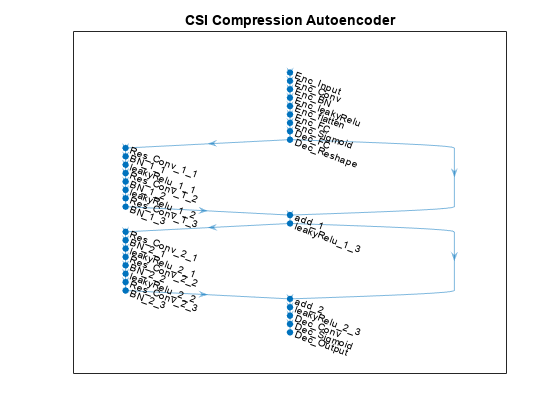

figure
plot(net)
title('CSI Compression Autoencoder')

## **Data Loading**

if strcmp(envir,'indoor')==1
    load('data/DATA_Htestin.mat');
    x_test = HT;
elseif strcmp(envir,'outdoor')==1
    load('data/DATA_Htestout.mat')
    x_test = HT;
end

x_test=single(x_test);
x_test_size=size(x_test,1);
X_test=zeros(img_height,img_width,img_channels,x_test_size);
for index=1:x_test_size
    X_test(:,:,:,index)=cat(3,reshape(x_test(index,1:end/2),32,32,1),reshape(x_test(index,end/2+1:end),32,32,1));
end

## Test Trained Network

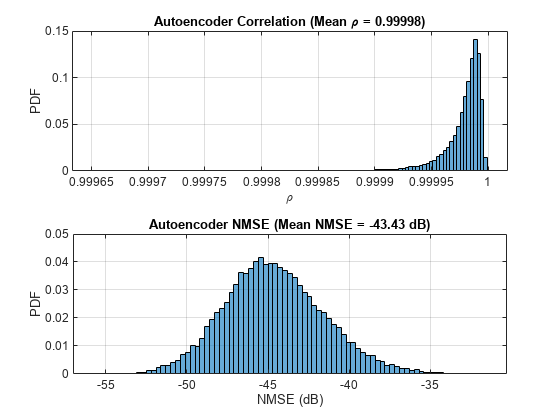

X_test_Hat = predict(net,X_test);

rho = zeros(x_test_size,1);
nmse = zeros(x_test_size,1);
for n=1:x_test_size
    in = X_test(:,:,1,n) + 1i*(X_test(:,:,2,n));
    out = X_test_Hat(:,:,1,n) + 1i*(X_test_Hat(:,:,2,n));

    % Calculate correlation
    n1 = sqrt(sum(conj(in).*in,'all'));
    n2 = sqrt(sum(conj(out).*out,'all'));
    aa = abs(sum(conj(in).*out,'all'));
    rho(n) = aa / (n1*n2);

    % Calculate NMSE
    mse = mean(abs(in-out).^2,'all');
    nmse(n) = 10*log10(mse / mean(abs(in).^2,'all'));
end

figure
tiledlayout(2,1)
nexttile
histogram(rho,"Normalization","probability")
grid on
title(sprintf("Autoencoder Correlation (Mean \\rho = %1.5f)",mean(rho)))
xlabel("\rho"); ylabel("PDF")
nexttile
histogram(nmse,"Normalization","probability")
grid on
title(sprintf("Autoencoder NMSE (Mean NMSE = %1.2f dB)",10*log10(mean(10.^(nmse/10)))))
xlabel("NMSE (dB)"); ylabel("PDF")

## Calculate rho & NMSE in Frequency Domain

if strcmp(envir,'indoor')==1
    load('data/DATA_HtestFin_all.mat');
    x_test_all = HF_all;

elseif strcmp(envir,'outdoor')==1
    load('data/DATA_HtestFout_all.mat')
    x_test_all = HF_all;

end

x_test_all=single(x_test_all);
X_test_all=zeros(125,img_width,x_test_size);
for index=1:x_test_size
    X_test_all(:,:,index)=reshape(x_test_all(index,:),125,img_width);
end

rho=zeros(1,x_test_size);
MSE=zeros(1,x_test_size);
power=zeros(1,x_test_size);

for index=1:20000
    H=X_test(:,:,:,index);
    HH=(H(:,:,1)-0.5)+1i*(H(:,:,2)-0.5);
    power(index)=sum(abs(HH).^2,'all');

    H_pred=X_test_Hat(:,:,:,index);
    HH_pred=(H_pred(:,:,1)-0.5)+1i*(H_pred(:,:,2)-0.5);

    MSE(index)=sum(abs(HH_pred-HH).^2,'all');

    HH_pred_Fin=[HH_pred;zeros(257-img_height,32)];
    HH_pred_Fin=fft(HH_pred_Fin,[],1);
    HH_pred_Fin=HH_pred_Fin(1:125,:);

    HH_Fin=X_test_all(:,:,index);

    n1=sqrt(sum(conj(HH_pred_Fin).*HH_pred_Fin,2));
    n2=sqrt(sum(conj(HH_Fin).*HH_Fin,2));
    aa=abs(sum(conj(HH_pred_Fin).*HH_Fin,2));
    rho(index)=mean(aa./(n1.*n2));
end

rho_Avg=mean(rho)

rho_Avg = 0.9857

MSE_Avg=mean(MSE)

MSE_Avg = 0.0233

NMSE=10*log10(mean(MSE./power))

NMSE = -16.2360

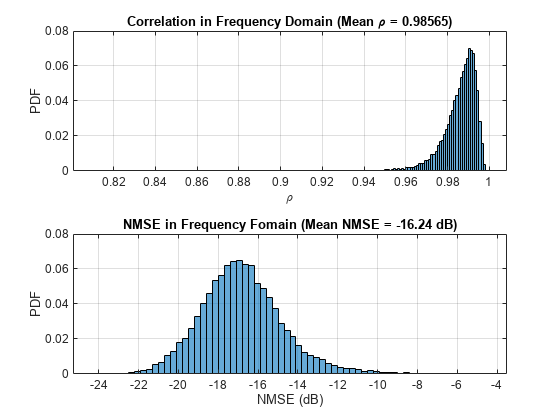


figure
tiledlayout(2,1)
nexttile
histogram(rho,"Normalization","probability")
grid on
title(sprintf("Correlation in Frequency Domain (Mean \\rho = %1.5f)",rho_Avg))
xlabel("\rho"); ylabel("PDF")
nexttile
histogram(10*log10(MSE./power),"Normalization","probability")
grid on
title(sprintf("NMSE in Frequency Fomain (Mean NMSE = %1.2f dB)",NMSE))
xlabel("NMSE (dB)"); ylabel("PDF")
saveas(gcf,"Sigmoid result\"+model_name+".jpg")

## Split Encoder & Decoder

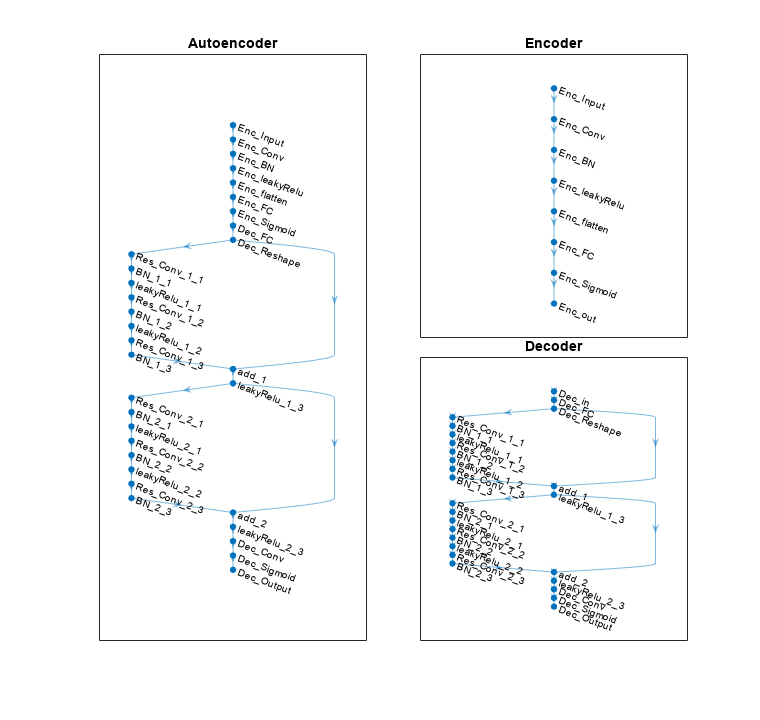

[encNet,decNet] = helperCSINetSplitEncoderDecoder(net,"Enc_Sigmoid");
plotNetwork(net,encNet,decNet)

## End-to-End CSI Feedback System

codeword = predict(encNet,X_test);
X_test_hat = predict(decNet,codeword);

for index=1:20000
    H=X_test(:,:,:,index);
    HH=(H(:,:,1)-0.5)+1i*(H(:,:,2)-0.5);
    power(index)=sum(abs(HH).^2,'all');

    H_pred=X_test_hat(:,:,:,index);
    HH_pred=(H_pred(:,:,1)-0.5)+1i*(H_pred(:,:,2)-0.5);

    MSE(index)=sum(abs(HH_pred-HH).^2,'all');

    HH_pred_Fin=[HH_pred;zeros(257-img_height,32)];
    HH_pred_Fin=fft(HH_pred_Fin,[],1);
    HH_pred_Fin=HH_pred_Fin(1:125,:);

    HH_Fin=X_test_all(:,:,index);

    n1=sqrt(sum(conj(HH_pred_Fin).*HH_pred_Fin,2));
    n2=sqrt(sum(conj(HH_Fin).*HH_Fin,2));
    aa=abs(sum(conj(HH_pred_Fin).*HH_Fin,2));
    rho(index)=mean(aa./(n1.*n2));
end

rho_Avg=mean(rho)

rho_Avg = 0.9857

MSE_Avg=mean(MSE)

MSE_Avg = 0.0233

NMSE=10*log10(mean(MSE./power))

NMSE = -16.2360

## Effect of Quantized Codewords

nBitsVec = 2:10;
rho_all=zeros(1,length(nBitsVec));
MSE_Avg_all=zeros(1,length(nBitsVec));
NMSE_all=zeros(1,length(nBitsVec));

for numBits_index=1:length(nBitsVec)
    disp("Running for " + nBitsVec(numBits_index) + " bit quantization")

    % Quantize between 0:2^n-1 to get bits
    qCodeword = uencode(double(codeword*2-1), nBitsVec(numBits_index));
    % Get back the floating point, quantized numbers
    codewordRx = (single(udecode(qCodeword,nBitsVec(numBits_index)))+1)/2;
    X_test_hat_quantized = predict(decNet,codewordRx);

    for index=1:20000
        H=X_test(:,:,:,index);
        HH=(H(:,:,1)-0.5)+1i*(H(:,:,2)-0.5);
        power(index)=sum(abs(HH).^2,'all');

        H_pred=X_test_hat_quantized(:,:,:,index);
        HH_pred=(H_pred(:,:,1)-0.5)+1i*(H_pred(:,:,2)-0.5);

        MSE(index)=sum(abs(HH_pred-HH).^2,'all');

        HH_pred_Fin=[HH_pred;zeros(257-img_height,32)];
        HH_pred_Fin=fft(HH_pred_Fin,[],1);
        HH_pred_Fin=HH_pred_Fin(1:125,:);

        HH_Fin=X_test_all(:,:,index);

        n1=sqrt(sum(conj(HH_pred_Fin).*HH_pred_Fin,2));
        n2=sqrt(sum(conj(HH_Fin).*HH_Fin,2));
        aa=abs(sum(conj(HH_pred_Fin).*HH_Fin,2));
        rho(index)=mean(aa./(n1.*n2));
    end

    rho_all(numBits_index)=mean(rho);
    MSE_Avg_all(numBits_index)=mean(MSE);
    NMSE_all(numBits_index)=10*log10(mean(MSE./power));

end

Running for 2 bit quantization
Running for 3 bit quantization
Running for 4 bit quantization
Running for 5 bit quantization
Running for 6 bit quantization
Running for 7 bit quantization
Running for 8 bit quantization
Running for 9 bit quantization
Running for 10 bit quantization


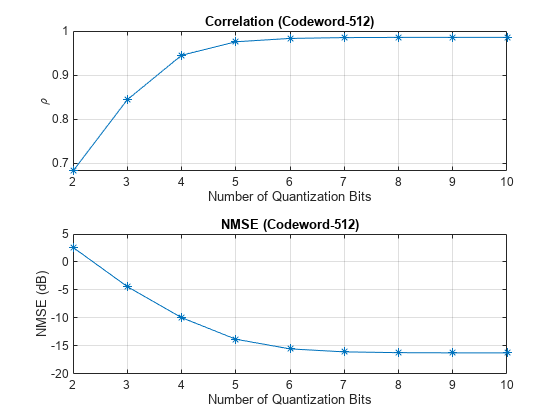

figure
tiledlayout(2,1)
nexttile
plot(nBitsVec,rho_all,'*-')
title("Correlation (Codeword-" + encoded_dim + ")")
xlabel("Number of Quantization Bits"); ylabel("\rho")
grid on
nexttile
plot(nBitsVec,NMSE_all,'*-')
title("NMSE (Codeword-" + encoded_dim + ")")
xlabel("Number of Quantization Bits"); ylabel("NMSE (dB)")
grid on
saveas(gcf,"Sigmoid result\"+model_name+"_Quantized.jpg")

save("Sigmoid result\"+model_name+"_Quantization_Result.mat",'nBitsVec','rho_all','NMSE_all')